This script runs through the basics of an optimal control problem using dynamic programming.  We will setup grids in the state and control spaces and then study the solution to the problem on the grid.  This approach is VERY storage intensive, and will not work for systems with complex dynamics.  I would limit such brute force to 4 states maximum.

System to Control

Let's solve the problem in class numerically


$$x(k+1) = x(k)+u(k)$$


Setup Discretized Space

X = [0:0.5:2]';  %Possible positions
U = [-1:0.5:1]';  %Initialize the control vector
N = 4;  %How many time steps?  I will iterate on this.
J = 1000*ones(length(X),N);  %Setup an initial large cost matrix - if the numbers don't change, that indicates infeasibility
Ustar = 1000*ones(length(X),N-1);  %The optimal control - clearly these values will shrink!  Give N-1 controls in all.

Cost Function

Terminal Cost

for jj = 1:length(X)
    J(jj,N) = 1/2*(X(jj))^2;  
end

Backward Solution

for ii = 1:N-1
    for jj = 1:length(X) 
            for ll = 1:length(U)
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %Calculate the next state - here are the system dynamics.
                Xn = X(jj)+U(ll);
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %Update the optimal costs / controls
                if (Xn <= X(end) & Xn >= X(1))  %If feasible
                    dJ = interpn(X,J(:,N-ii+1),Xn)+1/2*X(jj)^2+1/2*U(ll)^2;  %Cost-to-go
                    if dJ<J(jj,N-ii)
                        J(jj,N-ii) = dJ;
                        Ustar(jj,N-ii) = U(ll);
                    end
                end
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            end
    end
end

Forward Solution

Now we apply the optimal control and find the optimal trajectory given a starting point.

%Setup initial conditions
Xtraj(1) = 1;
%Find the optimal cost
interpn(X,J(:,1),Xtraj(1))

ans = 0.8750

%Find initial optimal control
Uact(1) = interpn(X,Ustar(:,1),Xtraj(1));
%Roll dynamics forward, calculating optimal controls as we go
for ii = 2:N-1
     Xtraj(ii) = Xtraj(ii-1)+Uact(ii-1);
     Uact(ii) = interpn(X,Ustar(:,ii),Xtraj(ii));
end
%Find the final values of the trajectory based on the final control input
Xtraj(ii+1) = Xtraj(ii)+Uact(ii);
 

Let's test the solution.

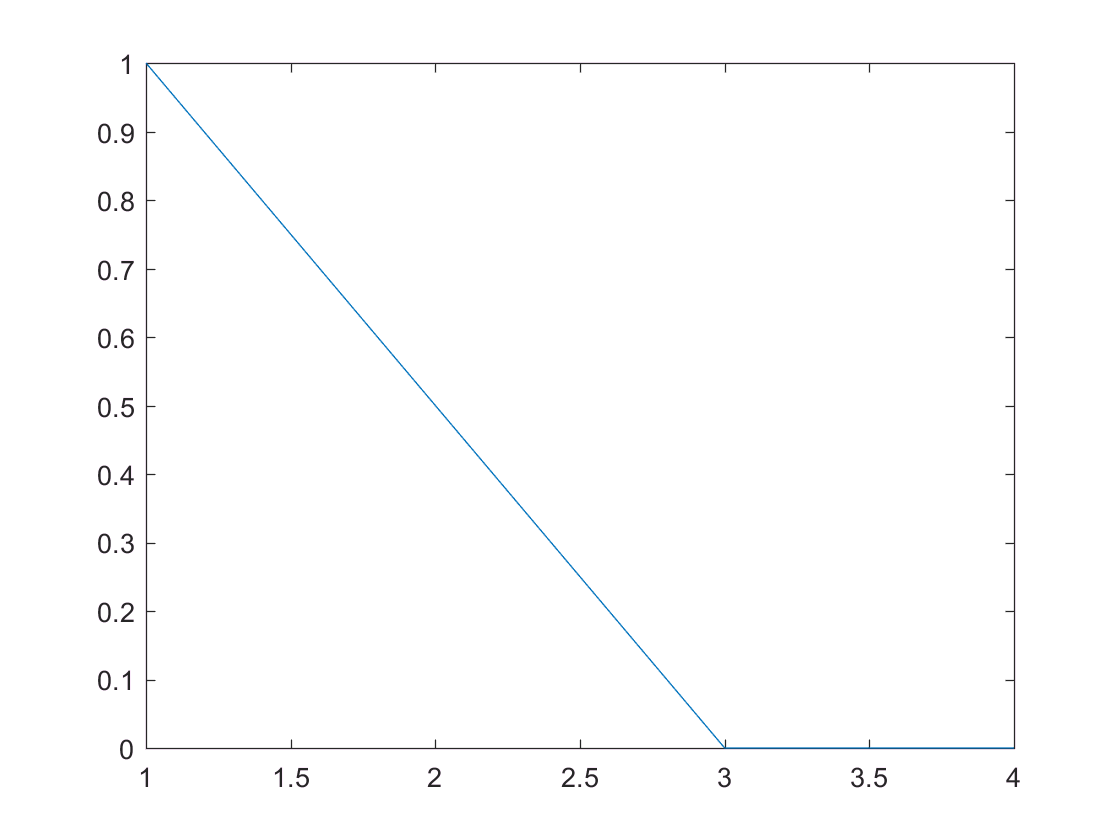

 plot([1:N],Xtraj)

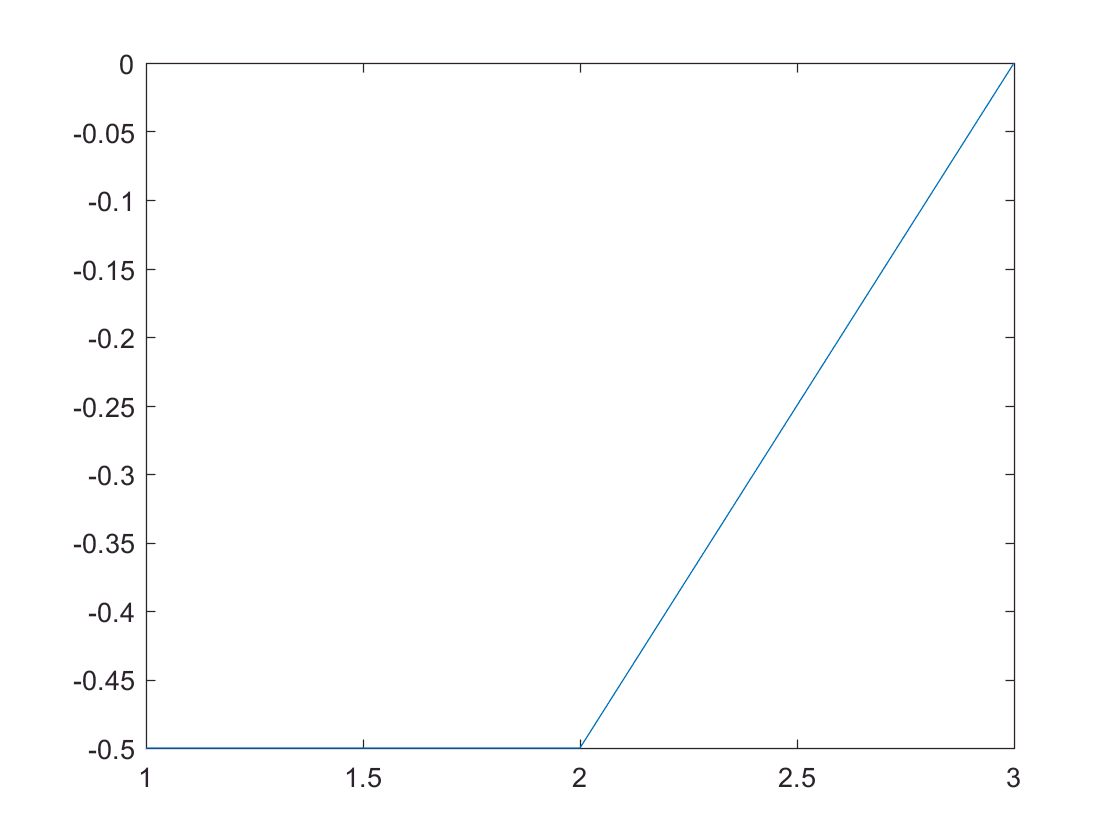

 plot([1:N-1],Uact)